## Tutorial 3: Understanding the preprocessing module

In this tutorial, we ...

To start with, we first simulate an example one-photon calcium imaging movie using the code:

if ~isfile('Example_1p_movie.h5')
    [opts_2p,opts_back] = get_1p_defaults();
    opts_2p.ns = 100;
    opts_2p.n_cell = 100;
    opts_back.ns = 100;
    opts_back.n_cell = 20;
    opts_back.cell_radius = [20,40];
    rng(1)
    create_1p_movie(opts_2p,opts_back,'Example_1p_movie');
end

### Reading and watching calcium movies

To load the calcium movies with h5read, we first need to :

info = h5info('Example_1p_movie.h5');
info.Datasets.Name

ans = 'mov'

info.Datasets.Dataspace

ans = struct with fields:
       Size: [100 100 5000]
    MaxSize: [100 100 5000]
       Type: 'simple'


This function provides the name of the dataset: '/mov'. The FOV is 100x100, and there are a total of 5000 frames. Now, we show how to use the h5read function native to Matlab to retrieve the first 1000 frames of the movie:

M = h5read('Example_1p_movie.h5','/mov', ...
    [1,1,1],[100,100,1000]);

More information on this function can be found in [this link](https://www.mathworks.com/help/matlab/ref/h5read.html).

EXTRACT has several helper functions. One particularly useful function allows visualizing the calcium imaging movies. Here is how to use it:

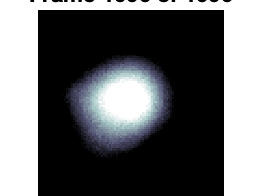

view_movie(M)

### Spatial high-pass filtering in EXTRACT

EXTRACT has an internal spatial band-pass filtering function, which we use to perform highpass filtering during the preprocessing module. Below is an example movie that is filtered to remove the neuropil contamination.

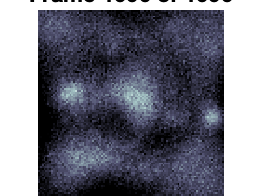

avg_cell_radius = 6;
spatial_highpass_cutoff = 5;
spatial_lowpass_cutoff = inf;
use_gpu = 0;
M_proc = spatial_bandpass(M, avg_cell_radius, ...
  spatial_highpass_cutoff, spatial_lowpass_cutoff, ...
  use_gpu);
view_movie(M_proc)

As shown in the movie on the right, the global background is removed with the selective high-pass spatial filtering and individual cell activities can easily be recovered.

#### Processing patches individually?

Now, what if we were to process this calcium imaging movie in spatial batches? How should we perform the high-pass filtering? An option is to upload the small batch and perform the filtering on it, which would give:

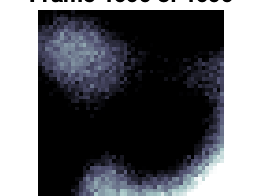

M_small = h5read('Example_1p_movie.h5','/mov', ...
    [1,1,1],[50,50,1000]);
M_proc_small = spatial_bandpass(M_small, avg_cell_radius, ...
  spatial_highpass_cutoff, spatial_lowpass_cutoff, ...
  use_gpu);
view_movie(M_proc_small)

Here, one can clearly obseve the edge effects that were not present in the original movie. These edge effects are expected, since we are performing a global spatial filtering on a local small spatial patch. 

#### Processing the full FOV?

A better alternative for spatial filtering is to process and save the full movie, but keep only the relevant fraction in RAM memory. In our example, following such a procedure, the small processed spatial patch would look as follows:

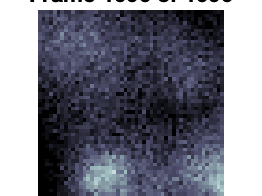

view_movie(M_proc(1:50,1:50,:))

This is a significant improvement compared to before. But, to achieve this, we had to keep the full movie in the memory. Or did we? 

### **Preprocessing and saving movies in batches**

Fortunately, the spatial filtering does not require any temporal information and can be parallelized across individual frames. Therefore, even when the full movie cannot be kept in memory, one can perform the spatial filtering in batches of few hundreds of frames. For EXTRACT, we provided the following helper function to facilitate this process:

config = get_defaults([]);
config.partition_size_time = 500;
preprocess_save('Example_1p_movie.h5:/mov',config)

03-Jul-2024 19:59:35: No GPU detected, using CPU instead
03-Jul-2024 19:59:35: Deleted the fileExample_1p_movie_final.h5
03-Jul-2024 19:59:35: Calculating F_per_pixel ... 
	 	 	 03-Jul-2024 19:59:35: Running 1 out of 5 parts 
	 	 	 03-Jul-2024 19:59:35: Running 2 out of 5 parts 
	 	 	 03-Jul-2024 19:59:35: Running 3 out of 5 parts 
	 	 	 03-Jul-2024 19:59:35: Running 4 out of 5 parts 
	 	 	 03-Jul-2024 19:59:35: Running 5 out of 5 parts 
03-Jul-2024 19:59:35: Running Highpass filtering ... 
	 	 	 03-Jul-2024 19:59:35: Running 1 out of 10 parts 
	 	 	 03-Jul-2024 19:59:36: Running 2 out of 10 parts 
	 	 	 03-Jul-2024 19:59:36: Running 3 out of 10 parts 
	 	 	 03-Jul-2024 19:59:36: Running 4 out of 10 parts 
	 	 	 03-Jul-2024 19:59:36: Running 5 out of 10 parts 
	 	 	 03-Jul-2024 19:59:36: Running 6 out of 10 parts 
	 	 	 03-Jul-2024 19:59:36: Running 7 out of 10 parts 
	 	 	 03-Jul-2024 19:59:36: Running 8 out of 10 parts 
	 	 	 03-Jul-2024 19:59:36: Running 9 out of 10 parts 
	 	 	 03-

The full preprocessed movie is saved as Example_1p_movie_final.h5. 

Here is how to use this movie to perform cell extraction:

M = h5read('Example_1p_movie_final.h5','/mov');

Error using h5readc
Unable to open 'Example_1p_movie_final.h5'. File or folder not found.

Error in h5read (line 93)
[data,var_class] = h5readc(Filename,Dataset,start,count,stride);

config = get_defaults([]);
config.preprocess = 0;
config.use_gpu = 0;
config.cellfind_max_steps = 120;
config.F_per_pixel = h5read('Example_1p_movie_final.h5','/F_per_pixel');
output = extractor(M,config);

a = load('Example_1p_movie.mat');

[recall,precision,ampcor,auc] = get_simulation_results(a,output);

fprintf("Prc %.3f. Rcl %.3f. Ampcor %.3f. AUC %.4f. \n", ...
    precision,recall,ampcor,auc);